Boxplot comparacio dades Amanda

Comparacio de les dades de l'Amanda per a veure les mitjanes i la distribució, si és normal o no.

dades_cru = readtable('C:\Users\jllobet\Desktop\Length determination v2_12\Probes_guardar\_Seguiment_desenvolupament\2022_10_13_Mesures manuals Fiji vs WM\2022_10_13_Mesura_correccio_FIJI_ImageJ\Dades_totals_juntes.xlsx')

dades_cru = 57×6 table
    C24_A     C48_A     C72_A     C24_WM    C48_WM    C72_WM
    ______    ______    ______    ______    ______    ______

    399.06    729.85    954.23    259.31    795.23    1093.6
     338.1    703.34    895.65    236.14    726.89     956.9
    474.77    663.11    1011.8    368.66    785.15    875.45
    348.25    753.32    1120.3    429.23    732.71    1022.7
    365.26    607.73    1037.8    367.33    713.76    1092.4
    335.09    903.59    1162.5    309.29    695.96    1012.8
    371.87     696.2    1199.7    397.47    693.71    1128.8
    387.62    709.86    986.51    491.72    628.93    1174.6
    466.08    727.41    1023.6    327.37    851.97    989.23
    415.06     735.8    1092.3    376.03    689.76    999.79
    352.33    688.35    813.62    372.68


propietats_dades_cru = dades_cru.Properties.VariableNames

propietats_dades_cru = 1×6 cell array
    {'C24_A'}    {'C48_A'}    {'C72_A'}    {'C24_WM'}    {'C48_WM'}    {'C72_WM'}


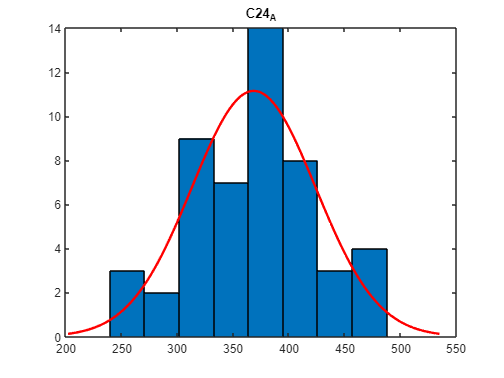

Shapiro test: No hi ha normalitat. p-val: 0.75503


descript_dades_sing = 7×1 table
                      C24_A 
                      ______

    mean              368.49
    std               55.473
    n                     50
    Std error mean    7.8451
    Max               480.01
    Min               247.59
    Range             232.42


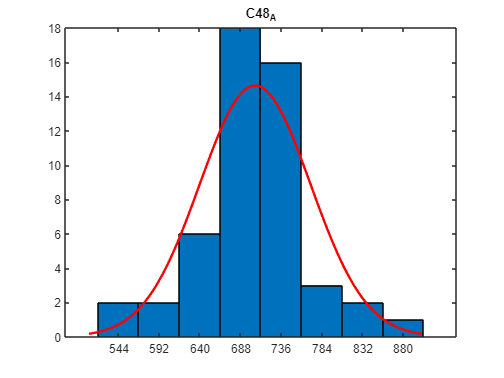

Shapiro test: Sí hi ha normalitat. p-val: 0.028553


descript_dades_sing = 7×1 table
                      C48_A 
                      ______

    mean              705.05
    std               65.395
    n                     50
    Std error mean    9.2482
    Max               903.59
    Min               532.49
    Range              371.1


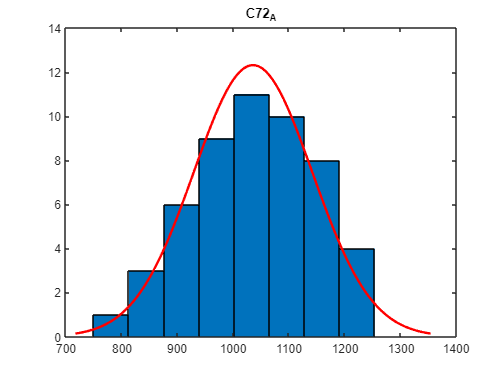

Shapiro test: No hi ha normalitat. p-val: 0.67909


descript_dades_sing = 7×1 table
                      C72_A 
                      ______

    mean              1035.5
    std               106.14
    n                     52
    Std error mean    14.719
    Max               1247.1
    Min                799.8
    Range             447.26


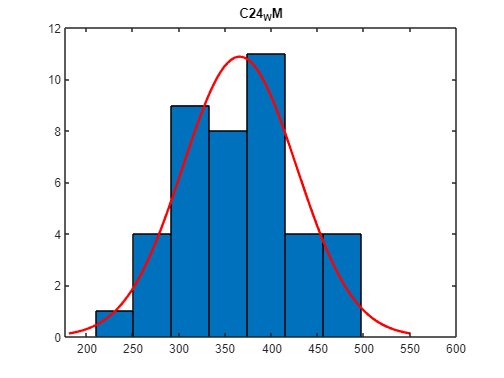

Shapiro test: No hi ha normalitat. p-val: 0.87855


descript_dades_sing = 7×1 table
                      C24_WM
                      ______

    mean              365.55
    std                61.61
    n                     41
    Std error mean    9.6218
    Max               491.72
    Min               236.14
    Range             255.58


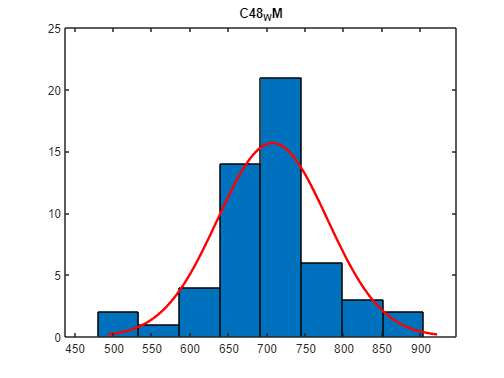

Shapiro test: Sí hi ha normalitat. p-val: 0.037411


descript_dades_sing = 7×1 table
                      C48_WM
                      ______

    mean              707.01
    std               71.471
    n                     53
    Std error mean    9.8173
    Max               902.02
    Min               517.09
    Range             384.93


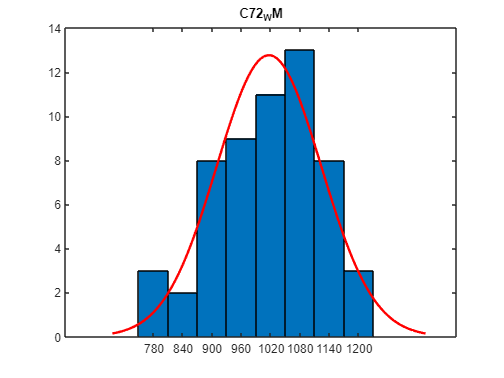

Shapiro test: No hi ha normalitat. p-val: 0.23794


descript_dades_sing = 7×1 table
                      C72_WM
                      ______

    mean              1016.3
    std               106.89
    n                     57
    Std error mean    14.158
    Max                 1229
    Min               791.37
    Range             437.59



descript_dades_total = [];
for variable_n = propietats_dades_cru

    variable_name = variable_n{1};

    dades_cru_singular = dades_cru{:,variable_name};

    % Treiem els NaN
    dades_cru_singular = dades_cru_singular(~isnan(dades_cru_singular));

    % Histfit
    figure; histfit(dades_cru_singular); hold on; title(variable_name); hold off;

%     % Probem normalitat
%     [ktest_res, p_val_ktest] = kstest(dades_cru_singular);

    % Shapiro test
    [shaptest, pValue, W] = swtest(dades_cru_singular); %x, alpha
    % H0: Hi ha normalitat.
    %   H=0 : No rebutja hipotesis nula : Hi ha normalitat
    %   H=1 : Rebutja hipotesis nula : NO hi ha normalitat.

    if shaptest
        disp(strcat("Shapiro test: Sí hi ha normalitat. p-val: ", string(pValue)))
    else
        disp(strcat("Shapiro test: No hi ha normalitat. p-val: ", string(pValue)))
    end

    % Estadística descriptiva
    descript_dades = {mean(dades_cru_singular); std(dades_cru_singular); ...
        numel(dades_cru_singular); ...
        std(dades_cru_singular) / sqrt(numel(dades_cru_singular)); ...
        max(dades_cru_singular); ...
        min(dades_cru_singular); ...
        max(dades_cru_singular) - min(dades_cru_singular)};

    descript_dades_sing = cell2table(descript_dades, 'VariableNames',variable_n, 'RowNames',["mean", "std", "n", "Std error mean", "Max", "Min", "Range"])

    if isempty(descript_dades_total)
        descript_dades_total = descript_dades_sing;
    else
        descript_dades_total = [descript_dades_total, descript_dades_sing];


    end
end


% Taula estadística descriptiva total:
descript_dades_total

descript_dades_total = 7×6 table
                      C24_A     C48_A     C72_A     C24_WM    C48_WM    C72_WM
                      ______    ______    ______    ______    ______    ______

    mean              368.49    705.05    1035.5    365.55    707.01    1016.3
    std               55.473    65.395    106.14     61.61    71.471    106.89
    n                     50        50        52        41        53        57
    Std error mean    7.8451    9.2482    14.719    9.6218    9.8173    14.158
    Max               480.01    903.59    1247.1    491.72    902.02      1229
    Min               247.59    532.49     799.8    236.14    517.09    791.37
    Range         </


[array_dades_tot, array_repetits_categories_categorical] = fer_boxplot_from_taula(dades_cru)

array_dades_tot = 	1.0e+03 *

    0.3991    0.3381    0.4748    0.3483    0.3653    0.3351    0.3719    0.3876    0.4661    0.4151    0.3523    0.3304    0.3952    0.3755    0.4677    0.3410    0.4272    0.4058    0.2834    0.3781    0.3801    0.3582    0.3069    0.4172    0.3950    0.3697    0.4298    0.3677    0.3039    0.3859    0.4800    0.3293    0.3827    0.3681    0.3114    0.3557    0.3228    0.3269    0.4174    0.3854    0.4145    0.3779    0.4171    0.3275    0.2986    0.2579    0.4516    0.2476    0.2573    0.3227


array_repetits_categories_categorical = 1×303 categorical array
     C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C24_A      C48_A      C48_A      C48_A      C48_A      C48_A      C48_A      C48_A      C48_A      C48_A      C48_A      C48_A      C48_A      C48_A      C48_A      C48_A      C48_A      C48_A      C48_A      C48_A      C48_A      C48_A      C48_A      C48_A      C48_A      C48_A      C48_A      C48_A      C48_A      C48_A      C48_A      C48_A      C48_A      C48_A      C48_A      C48_A  

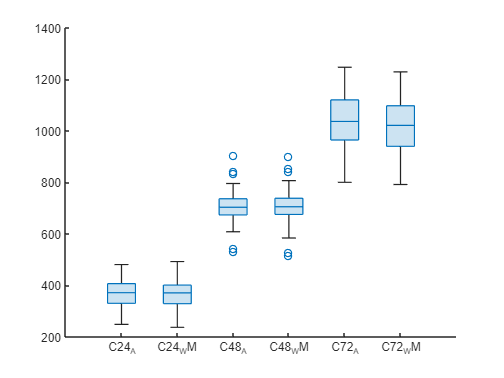

boxchart(array_repetits_categories_categorical, array_dades_tot)

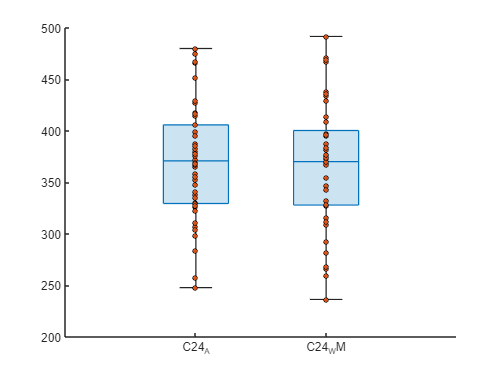

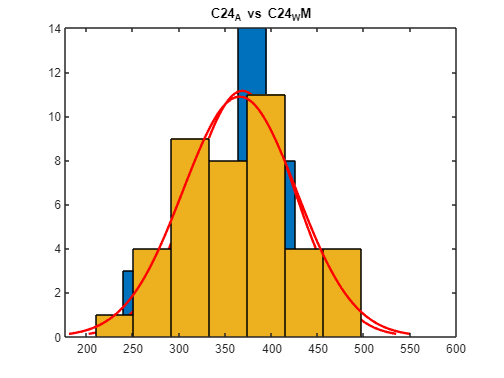

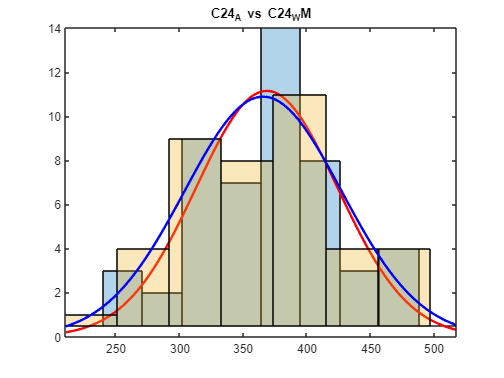

descript_dades_sing_tot = 7×2 table
                      C24_A     C24_WM
                      ______    ______

    mean              368.49    365.55
    std               55.473     61.61
    n                     50        41
    Std error mean    7.8451    9.6218
    Max               480.01    491.72
    Min               247.59    236.14
    Range             232.42    255.58


C24_A: Shapiro test: No hi ha normalitat. p-val: 0.75503


C24_WM: Shapiro test: No hi ha normalitat. p-val: 0.87855


Wilcoxon test


Wilcoxon test: Non-Reject H0: samples have same means. p-val: 0.83882


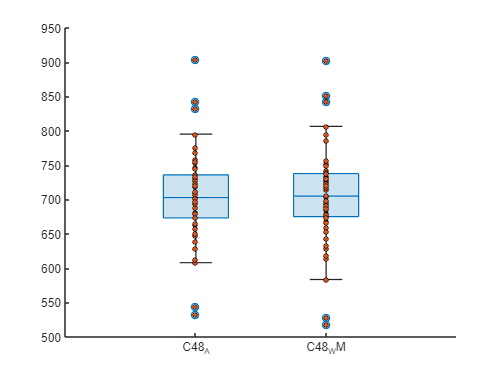

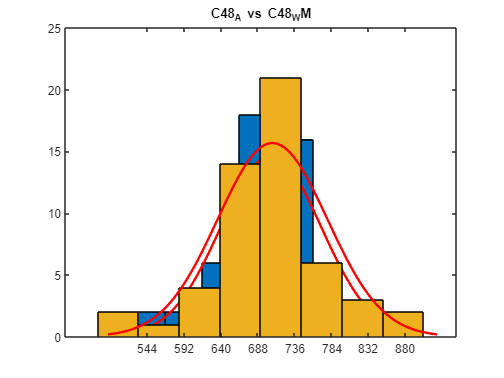

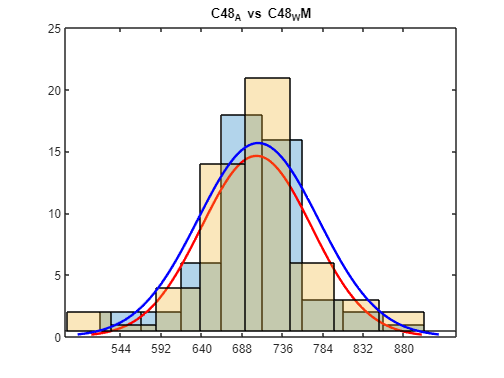

descript_dades_sing_tot = 7×2 table
                      C48_A     C48_WM
                      ______    ______

    mean              705.05    707.01
    std               65.395    71.471
    n                     50        53
    Std error mean    9.2482    9.8173
    Max               903.59    902.02
    Min               532.49    517.09
    Range              371.1    384.93


C48_A: Shapiro test: Sí hi ha normalitat. p-val: 0.028553


C48_WM: Shapiro test: Sí hi ha normalitat. p-val: 0.037411


Shapiro test


T-test: Not reject H0: samples have same means. p-val: 0.88549


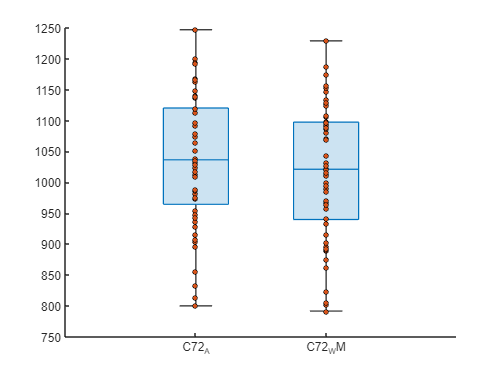

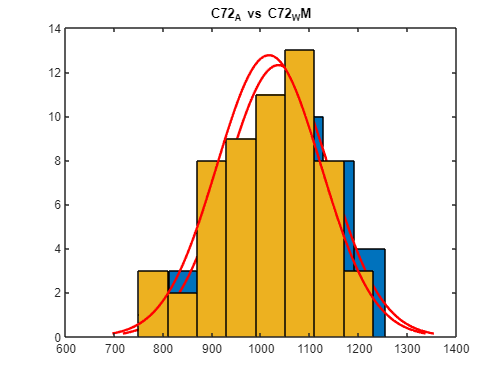

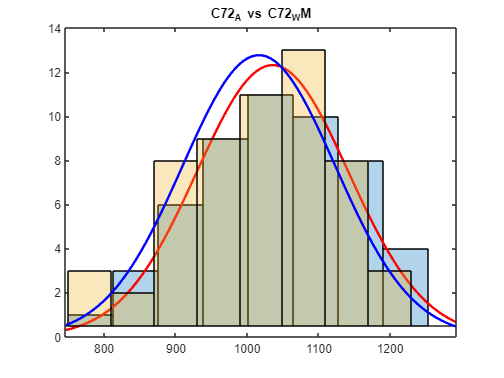

descript_dades_sing_tot = 7×2 table
                      C72_A     C72_WM
                      ______    ______

    mean              1035.5    1016.3
    std               106.14    106.89
    n                     52        57
    Std error mean    14.719    14.158
    Max               1247.1      1229
    Min                799.8    791.37
    Range             447.26    437.59


C72_A: Shapiro test: No hi ha normalitat. p-val: 0.67909


C72_WM: Shapiro test: No hi ha normalitat. p-val: 0.23794


Wilcoxon test


Wilcoxon test: Non-Reject H0: samples have same means. p-val: 0.35173




for n_var = 1:3
    % Taula temporal
    dades_cru_t = dades_cru(:,[n_var,n_var+3]);

    % Operacio obtenir boxplot
    [array_dades_tot, array_repetits_categories_categorical] = fer_boxplot_from_taula(dades_cru_t);


    % Graficació boxplot
    figure; boxchart(array_repetits_categories_categorical, array_dades_tot);
    hold on
    scatter(array_repetits_categories_categorical, array_dades_tot, 15, 'filled', 'MarkerEdgeColor', [0 0 0])
    hold off

    % Comparacio entre els dos:
    variable_names_sing = dades_cru_t.Properties.VariableNames;

    variable_names_sing_1 = variable_names_sing{1};
    variable_names_sing_2 = variable_names_sing{2};
%     dades_cru_sing1 = dades_cru(:,[n_var]);
%     dades_cru_sing2 = dades_cru(:,[n_var+3]);

    dades_cru_sing1 = dades_cru{:,variable_names_sing_1};
    dades_cru_sing2 = dades_cru{:,variable_names_sing_2};

    % Treiem NaN:
    dades_cru_sing1 = dades_cru_sing1(~isnan(dades_cru_sing1));
    dades_cru_sing2 = dades_cru_sing2(~isnan(dades_cru_sing2));


    % __Descripció hisfit__

    nom_titol = strcat(variable_names_sing_1, " vs ", variable_names_sing_2);

    % __Descripció hisfit 1__
    figure
    histfit(dades_cru_sing1); hold on; histfit(dades_cru_sing2); 
    title(nom_titol);
    hold off

    % __Descripció hisfit 2__
    % Definim punts minims i maxims de la grafica
    punt_min = min([dades_cru_sing1; dades_cru_sing2]);
    punt_max = max([dades_cru_sing1; dades_cru_sing2]);

    % Rang ( per a definir lim x)
    rangminmax = punt_max - punt_min;
    rangminmax_lim = rangminmax * 0.1;

    figure
    h1 = histfit(dades_cru_sing1);
    set(gca, 'XLim', [punt_min-rangminmax_lim  punt_max+rangminmax_lim])
    h1(1).BaseValue = 0.5;
    h1(1).FaceAlpha = 0.3;
    hold on
    h2 = histfit(dades_cru_sing2);
    h2(1).BaseValue = 0.5;
    h2(1).FaceAlpha = 0.3;
    h2(2).Color = "blue";
    title(nom_titol)

    %legend([h1 h2], variable_names_sing_1, variable_names_sing_2)

    hold off



    % Descripció dades estadística descriptiva:
    % Estadística descriptiva dades 1
    descript_dades = {mean(dades_cru_sing1); std(dades_cru_sing1); ...
        numel(dades_cru_sing1); ...
        std(dades_cru_sing1) / sqrt(numel(dades_cru_sing1)); ...
        max(dades_cru_sing1); ...
        min(dades_cru_sing1); ...
        max(dades_cru_sing1) - min(dades_cru_sing1)};

    descript_dades_sing_1 = cell2table(descript_dades, 'VariableNames', {variable_names_sing_1}, 'RowNames', ["mean", "std", "n", "Std error mean", "Max", "Min", "Range"]);


        % Estadística descriptiva dades 2
    descript_dades = {mean(dades_cru_sing2); std(dades_cru_sing2); ...
        numel(dades_cru_sing2); ...
        std(dades_cru_sing2) / sqrt(numel(dades_cru_sing2)); ...
        max(dades_cru_sing2); ...
        min(dades_cru_sing2); ...
        max(dades_cru_sing2) - min(dades_cru_sing2)};

    descript_dades_sing_2 = cell2table(descript_dades, 'VariableNames',{variable_names_sing_2}, 'RowNames',["mean", "std", "n", "Std error mean", "Max", "Min", "Range"]);
    
descript_dades_sing_tot = [descript_dades_sing_1, descript_dades_sing_2]



% ___Comparació de dades___


    % _Determinació normalitat_
    
    % Shapiro test 1
    [shaptest_1, pValue_1, W] = swtest(dades_cru_sing1); %x, alpha
    % H0: Hi ha normalitat.
    %   H=0 : No rebutja hipotesis nula : Hi ha normalitat
    %   H=1 : Rebutja hipotesis nula : NO hi ha normalitat.

    if shaptest_1
        disp(strcat(variable_names_sing_1, ": Shapiro test: Sí hi ha normalitat. p-val: ", string(pValue_1)))
    else
        disp(strcat(variable_names_sing_1, ": Shapiro test: No hi ha normalitat. p-val: ", string(pValue_1)))
    end



    % Shapiro test 2
    [shaptest_2, pValue_2, W] = swtest(dades_cru_sing2); %x, alpha
    % H0: Hi ha normalitat.
    %   H=0 : No rebutja hipotesis nula : Hi ha normalitat
    %   H=1 : Rebutja hipotesis nula : NO hi ha normalitat.

    if shaptest_2
        disp(strcat(variable_names_sing_2, ": Shapiro test: Sí hi ha normalitat. p-val: ", string(pValue_2)))
    else
        disp(strcat(variable_names_sing_2, ": Shapiro test: No hi ha normalitat. p-val: ", string(pValue_2)))
    end
        
    % Si hi ha normalitat en les dades: Shapiro test
    if shaptest_1 && shaptest_1
        % Si hi ha normalitat: unpaired t test
        disp("Shapiro test")
        [ttest_result, ttest_p] = ttest2(dades_cru_sing1, dades_cru_sing2);
    
        % Test the null hypothesis that the two data samples are from populations with equal means
        % ttest_result = 0: Not reject H0 : Igual mitjanes
    
        if ~ttest_result
            disp(strcat("T-test: Not reject H0: samples have same means. p-val: ", string(ttest_p)))
        else
            disp(strcat("T-test: Reject H0: samples have different means. p-val: ", string(ttest_p)))
        end
    
    else
    % Si no hi ha normalitat: suma de rangos de Wilcoxon
        disp("Wilcoxon test")
        [wilcox_pval, wilcox_result] = ranksum(dades_cru_sing1, dades_cru_sing2);
    
        % H0: Equal medians
        % wilcox_result = 1:  rejection of the null hypothesis: Different means.
    
        if ~wilcox_result
            disp(strcat("Wilcoxon test: Non-Reject H0: samples have same means. p-val: ", string(wilcox_pval)))
        else
            disp(strcat("Wilcoxon test: Reject H0: samples have different means. p-val: ", string(wilcox_pval)))
        end
    
    
    
    end    

end